FAST_plot2
% 读取节点位置信息
nodeData = readtable('附件1.csv');

nodeIDs = nodeData{:, 1}; % 节点编号
x = nodeData{:, 2}; % x坐标
y = nodeData{:, 3}; % y坐标
z = nodeData{:, 4}; % z坐标

% 读取三角形信息
triangleData = readtable('附件3.csv');

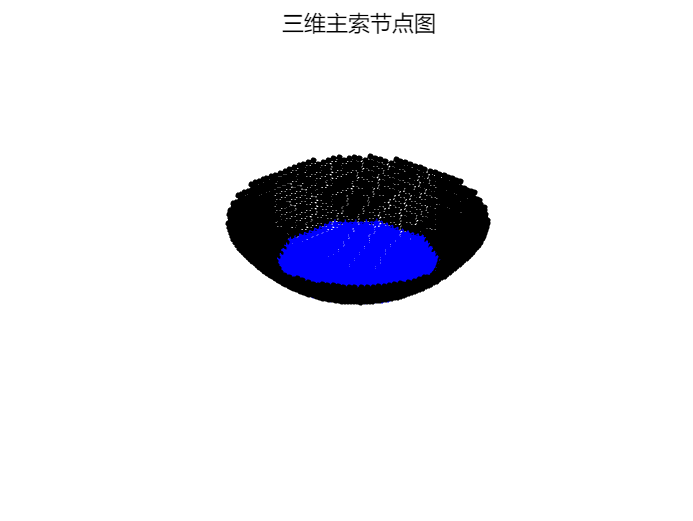

triNode1 = triangleData{:, 1}; % 第一个节点编号
triNode2 = triangleData{:, 2}; % 第二个节点编号
triNode3 = triangleData{:, 3}; % 第三个节点编号

% 创建一个映射表，将节点编号映射到索引
nodeIDMap = containers.Map(nodeIDs, 1:length(nodeIDs));

% 绘制三维图形
fig = figure;
set(fig, 'Position', [100, 100, 800, 600]); % 设置图形位置和大小
hold on;
axis equal;
axis off; % 隐藏坐标轴
view(3); % 设置为三维视角

% 绘制所有的节点
for i = 1:length(x)
    if z(i) < -259
        scatter3(x(i), y(i), z(i), 10, 'b', 'filled'); % 蓝色
    else
        scatter3(x(i), y(i), z(i), 10, 'k', 'filled'); % 黑色
    end
end

% 绘制三角形边界
for i = 1:height(triangleData)
    % 获取每个三角形的节点索引
    idx1 = nodeIDMap(triNode1{i});
    idx2 = nodeIDMap(triNode2{i});
    idx3 = nodeIDMap(triNode3{i});
    
    % 获取每个三角形的节点坐标
    x_tri = [x(idx1), x(idx2), x(idx3), x(idx1)];
    y_tri = [y(idx1), y(idx2), y(idx3), y(idx1)];
    z_tri = [z(idx1), z(idx2), z(idx3), z(idx1)];
    
    % 判断颜色
    if any(z_tri < -259)
        color = 'b'; % 蓝色
    else
        color = 'k'; % 黑色
    end
    
    % 绘制三角形边界
    plot3(x_tri, y_tri, z_tri, color); 
end